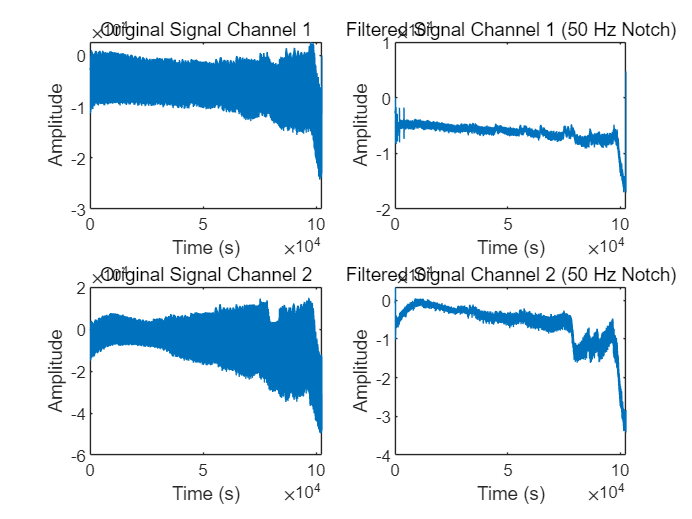

% 设定采样频率
fs = 250;

% 设计一个带阻滤波器，中心频率50 Hz
f0 = 50;  % 目标频率
bw = 2;  % 带宽
Q = f0/bw;  % 质量因数

% 使用designfilt创建带阻滤波器
d = designfilt('bandstopiir', 'FilterOrder', 2, 'HalfPowerFrequency1', ...
               f0-bw/2, 'HalfPowerFrequency2', f0+bw/2, 'DesignMethod', ...
               'butter', 'SampleRate', fs);

% 生成测试信号（含50 Hz干扰），两个通道
x=emg_div;

% 应用带阻滤波器到每个通道
y1 = filtfilt(d, x(:,1));
y2 = filtfilt(d, x(:,2));
y = [y1, y2];

% 绘制原始信号和滤波后的信号
figure;
subplot(2,2,1);
plot(x(:,1));
title('Original Signal Channel 1');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,2,2);
plot(y1);
title('Filtered Signal Channel 1 (50 Hz Notch)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,2,3);
plot(x(:,2));
title('Original Signal Channel 2');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,2,4);
plot(y2);
title('Filtered Signal Channel 2 (50 Hz Notch)');
xlabel('Time (s)');
ylabel('Amplitude');